if(~exist(strcat('g2s.',mexext), 'file'))
   CompileG2S; 
end

source=imread('source.png');
set(0,'DefaultFigureWindowStyle','docked')

## simple echo

data=g2s('-a','echo','-ti',single(source))/255;

Send job
job Id is: 3771764405
progres 0.000%
progres 100.000%


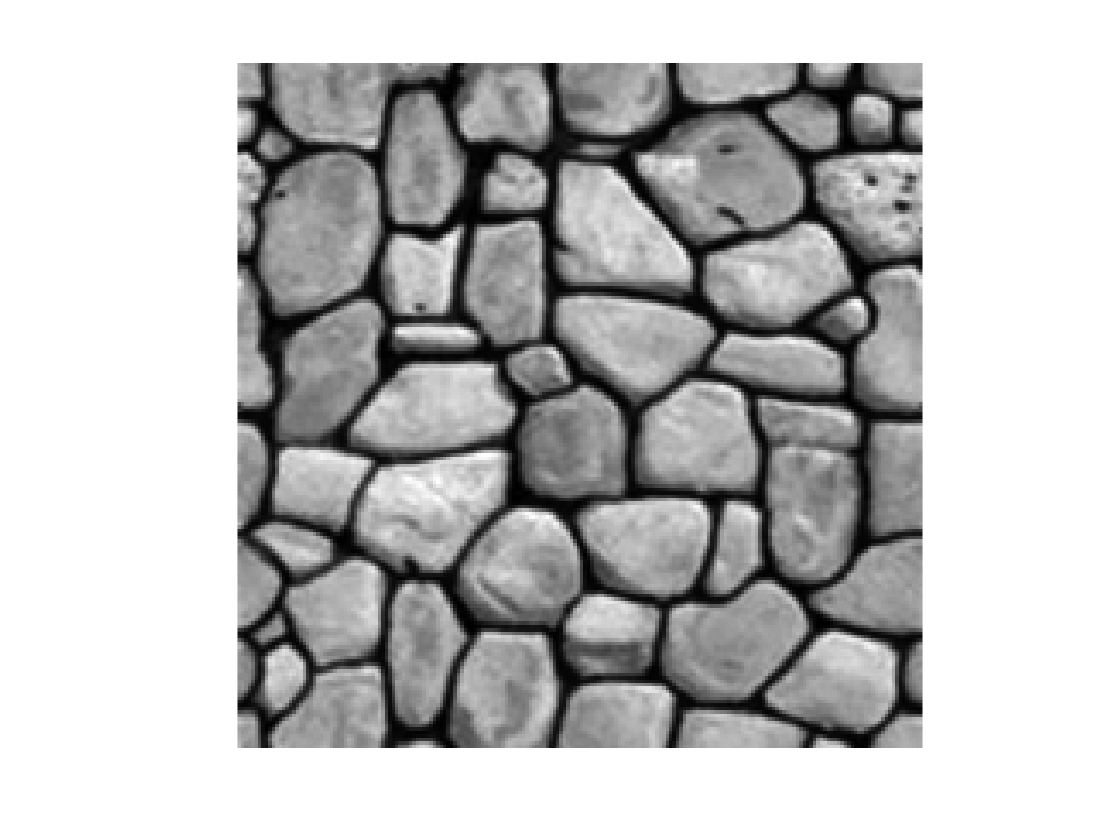

imshow(data);

## simple non conditional simulation with QS

data=(g2s('-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100)/255);
imshow(data)

%with GPU is integrated GPU avaible
data=(g2s('-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-W_GPU')/255);
imshow(data)

## simple conditional simulation with QS

pourcantage=0.25; %% 0.25%
dest=nan.*ones(200);
sizeDest=length(dest(:));

position=randperm(sizeDest,sizeDest*pourcantage/100);

dest(position)=source(position);

% simuulation of the source
data=(g2s('-a','qs','-ti',single(source),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);
imshow(data)

% simulation with random value at random position
dest=dest*nan;
position2=randperm(sizeDest,sizeDest*pourcantage/100);
dest(position2)=source(position);

% simuulation of the source
data=(g2s('-a','qs','-ti',single(source),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);
imshow(data)

## simple non conditional simulation with multi TI of differente size

data=(g2s('-a','qs','-ti',single(source(:,1:150)),single(rot90(source,1)),single(rot90(source(:,1:175),2)),single(rot90(source(:,1:150),3)),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);
imshow(data)

## simulation with a fixed path

% row path
path=zeros(200);
path(:)=(1:200*200);
data=(g2s('-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-sp',path)/255);
imshow(data)

% pathial random path
path=zeros(200);
path(:)=randperm(200*200);
path(randperm(200*200,200*200/2))=-inf;
data=(g2s('-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-sp',path)/255);
imshow(data)

## specifing a kernel

% ? kernel need to be define for each variable 

kernel=zeros(101,101);
kernel(51,51)=1;
kernel=exp(-0.1*bwdist(kernel));

data=(g2s('-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-ki',kernel)/255);
imshow(data)

## multi variete

source3=cat(3,source,source,source); %% need to fine better example
data=(g2s('-a','qs','-ti',single(source3),'-di',single(nan.*ones(200,200,3)),'-k',2,'-n',50,'-s',100)/255);
imshow(data)

## ds mode

data=(g2s('-a','ds-l','-ti',single(source),'-di',single(nan.*ones(200)),'-th',10,'-f',0.3,'-n',50,'-s',100)/255);